**Dear Students, **

**Welcome to Lab 1 - Part 2!**

**In this lab, we will explore implementation techniques of the convolution sum.  **

#### **Note: **

- **In this notebook, you are expected to (i) write or/and complete code snippets (ii) write your observations and inferences based on the results of the code. You can write your answers inferences just after the question where ANSWER is mentioned. **

- **If you feel that some information is missing for carrying out your exercises, you can assume them appropriately. Please remember to state your assumptions.  If you find typos in the notebook, please let us know.  **

**You are expected to submit the solved notebook by 24th October 2020, 11.59pm. **

### **References: **

- **https://classroom.google.com/u/0/w/MTUyODczMTg4NDQ2/tc/MTU1MDg5NDgyMjY5**

# **Slow and Fast Convolutions (100 Points)**

## **Learning Outcome**: 

At the end of this lab exercise, you will be able to implement the convolution operation to compute the output of a system given an input sequence and the impulse response of the system, using two different techniques. The technique we will explore are:

- Direct or Slow Convolution

- Fast Convolution 

## Background:

In the theory part, you studied about 4 ways of representing a linear time-invariant  (LTI) system [1, 4]. They are

- Impulse response, denoted by $h[n]$

- Frequency response, denoted by $H(e^{j\omega})$

- System function (Z-transform), denoted by $H(z
)$

- Linear Constant Coefficient Difference Equation, which is $y[n] = - \sum_{k=1}^Na_k y[n-k] + \sum_{k=0}^M b_kx[n-k]$. 

Each one of the above representations play a vital role in design and/or implementation of digital systems (such as filters). 

In this lab, we will talk about implementation of a system with finite impulse response (FIR) by convolving the input sequence with the impulse response of the system. 

## Direct or Slow Convolution:

In an FIR filter, we have, $h[n]\geq 0, \text{for}\; N_1\leq n \leq N_2
$ and $h[n] = 0
$ otherwise. For simplicity, let us assume, $N_1 = 0
$ and $N_2 = L_h-1
$. Such a filter is called as an $L_h$-length FIR filter. Now, given an input sequence, $x[n]$, of length $L_x$ (what does it mean? :- it is the length of the sequence $x[n]$),  we can compute the output sequence by the following convolution sum:  

                                                          $y[n] =  \sum_{k=0}^{L_h-1}h[k]x[n-k]$ for $n\in \mathbb{Z}$  

It is interesting to note that the above convolution sum has the form of the following LCCDE, $y[n] =  \sum_{k=0}^{L_h-1}b_kx[n-k]$, where $b_k = h[k]$ for $k=0,\ldots, L_h-1$. The above approach of computing convolution by direct evaluation of the convolution sum is called the Direct or Slow Convolution. The reason why it is called as the "Slow" convolution will be clear at the end of the notebook.

Let us write some code to implement this convolution.

### **Coding Question 1 (10 Points): **

- Generate the impulse response, $h[n]$, of a causal moving average filter of an arbitrary length, $L_h$. 

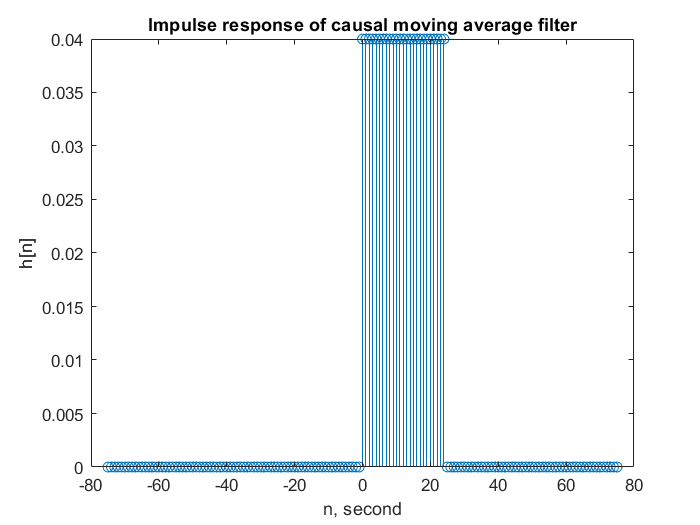

% Write your code here
Lh = 25;
n = -3*Lh : 1 : 3*Lh;
h = (n>=0 & n<Lh);
h = h / Lh;

stem(n,h);
title('Impulse response of causal moving average filter')
xlabel('n, second')
ylabel('h[n]')

- Generate a discrete-time sequence, $x[n]$ of an arbitrary length, $L_x$. 

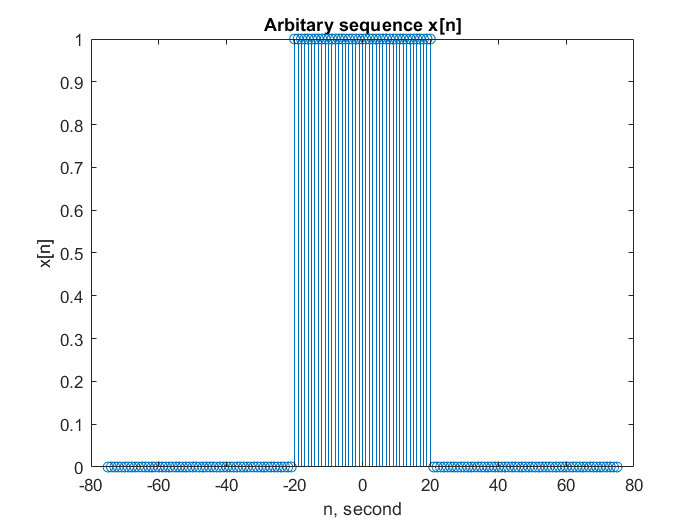

% Write your code here
Lx = 40;
a = pi/10;
x =  n>=-Lx/2 & n<=Lx/2;   %sin(a*n);

stem(n,x);
title('Arbitary sequence x[n]');
xlabel('n, second');
ylabel('x[n]');

- Compute $y[n] = h[n]\ast x[n]$by evaluating the convolution sum. 

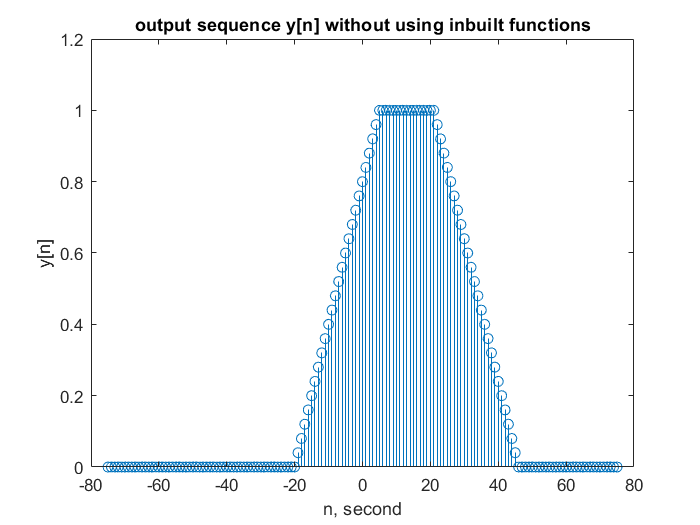

% Write your code here
y =  zeros(1,length(n));

j = 1;
while x(j) == 0
    j = j + 1;
end

L1 = j - 1 ;  %L1 is the position of first non zero element of y[n]

for i = L1 :  L1 + (Lx + Lh + 1)  %i iterates from position of first non zero element of y[n] to the last non zero elememt of y[n]    
    for k = 1 : Lh + 1
        y(i) = y(i) + h(k - n(1))*x(i - k);
    end
end

stem(n,y);
title('output sequence y[n] without using inbuilt functions');
xlabel('n, second');
ylabel('y[n]');

- Verify your answer using the inbuilt Matlab function, [conv](https://in.mathworks.com/help/matlab/ref/conv.html). 

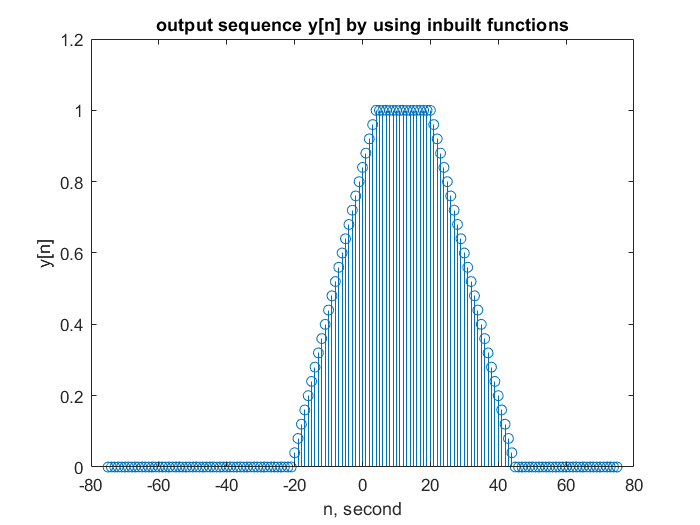

% Write your code here
y1 = conv(h,x , "same");
stem(n,y1)
xlabel('n, second');
ylabel('y[n]');
title("output sequence y[n] by using inbuilt functions");

### **Inference 1 (10 Points): **

- What is the maximum length of $y[n]$ over which it can be non-zero? Express your answer in terms of $L_h~\text{and} ~L_x$.

            ANSWER:  $L_x$ + $L_h$ - 1

- In order to compute $y[n_0]$, how many and which all samples of the input sequence $\{x[n]\}$ are required? What is the buffer memory requirement to store them? 

            ANSWER: We require a total of $L_h$ samples of the input sequence to calculate $y[n_0]$.

- Which kind of buffer would you use for the above convolution operation? (Hint: [https://en.wikipedia.org/wiki/Circular_buffer,](https://en.wikipedia.org/wiki/Circular_buffer,) [https://www.dspguide.com/ch28/2.htm](https://www.dspguide.com/ch28/2.htm))

            ANSWER:  To calculate the output sample, we must have access to a certain number of the most recent samples from the input (number recent samples required = $L_h$)

                                and the best way to manage these recent samples is through circular buffer.

## **Fast Convolution: **

Noting that discrete-time Fourier transform (DTFT) of $h[n]\ast x[n]$ is equal to $H(e^{j\omega})X(e^{j\omega})$, where $H(e^{j\omega}) = \text{DTFT}(h[n])$and $X(e^{j\omega}) = \text{DTFT}(X[n])$, we can consider the following approach for computing the convolution sum to obtain $y[n]$:

- Compute $H(e^{j\omega})$ and $X(e^{j\omega})$

- Obtain $Y(e^{j\omega})  =  H(e^{j\omega})X(e^{j\omega})$

- Compute the inverse DTFT of $Y(e^{j\omega})
$ to obtain $y[n]$. 

If we are able to do the above operations more efficiently than the direct computation of the convolution sum, we could adopt this approach. We will explore this in the below. 

Let us code a bit. 

### **Coding Question 2 (10 Points):**

- Compute and plot the DTFT of $h[n]$ you generated above, over $0\leq \omega <2\pi$.  

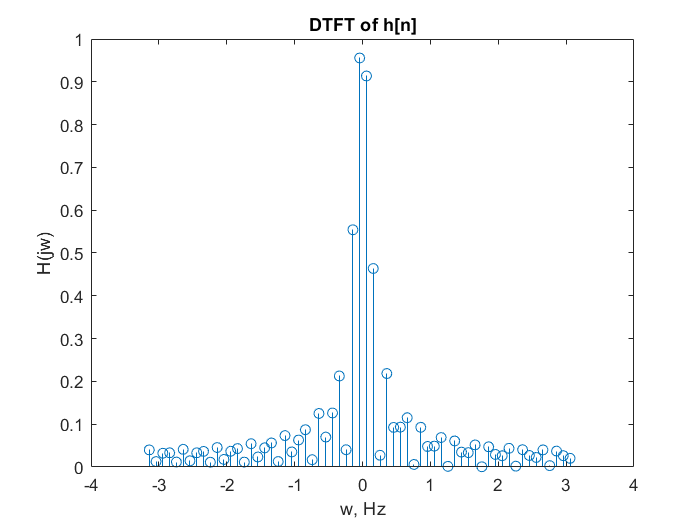

% WRITE YOUR CODE HERE. 
wstep = 0.1;
w = -pi : wstep : pi;
H = zeros(1,length(w));

for j = 1 : Lh + 1
    H = H + h(j + 3*Lh)*exp(-1i*w*j);
end

stem(w,abs(H));
xlabel('w, Hz');
ylabel('H(jw)');
title("DTFT of h[n]");

### **Coding Question 3 (10 Points):**

- Write a code snippet to reconstruct $h[n]$ from the DTFT you have computed

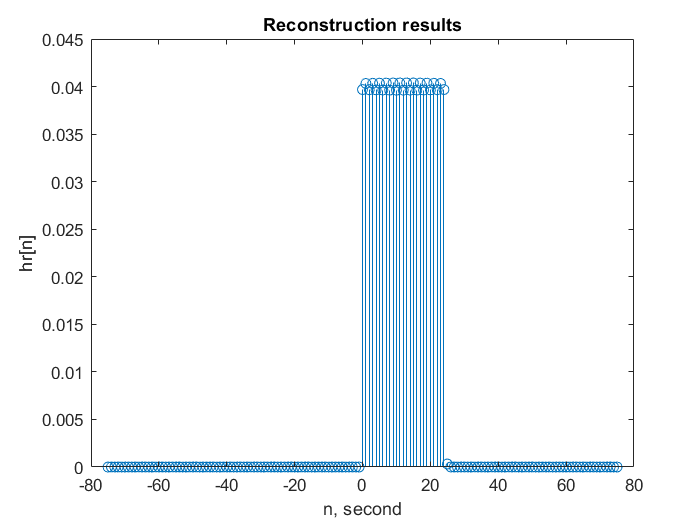

% WRITE YOUR CODE HERE.
hr = zeros(1,length(n));
for k = 1 : Lh + 1
    hr(k+3*Lh) = trapz(w,H.*exp(1i*w*k))/(2*pi);
end

stem(n,abs(hr));
xlabel('n, second');
ylabel('hr[n]');
title("Reconstruction results");

### Inference 2 **(10 Points):**

- Were you able to reconstruct $h[n]$ from $H(e^{j\omega})$? Why? Why not? 

            ANSWER: Yes, As we can see in the plot not all the points are at exact 0.04 amplitude but it is quite good reconstruction, these irregularities are a result of choosing higher value of step size, we will get better reconstruction results if we decrease the step size.  

- Which parameters in your code affect the reconstructability? 

            ANSWER: The step size of Omega.

As you might have noted, one of the main challenges with adopting the above approach is that computing the DTFT in a digital computer is not possible as $\omega
$ is a continuous variable representing the digital frequency.  One way to deal this problem is by using the approach you have just used!  That is, by computing DTFT values at closely (usually uniformly) spaced sample values of $\omega
$, i.e., at $-\pi, -\pi+\delta\omega, \pi+2\delta\omega, \ldots, \pi-\delta\omega, \pi$ or at $0,  \delta\omega, 2\delta\omega, \ldots, 2\pi-\delta\omega, 2\pi$ (Recall that it is sufficient to compute the DTFT function only over a period of length$2\pi$.)  However, we should be careful with this approach in that, we should select $\delta \omega$ such that we are able to reconstruct $x[n] $from the sampled DTFT.  Let us assume that $\delta \omega =  \frac{2\pi}{N}$, where, we need to select $N$ such that we are able to recover/reconstruct inverse DTFT values without loss of information [2]. We will find such an $N$in the following. 

Assume a discrete-time sequence $x[n], -\infty<n<\infty$ and consider its DTFT  $X(e^{j\omega})$ at $\omega = \frac{2\pi}{N}k, \;\; k = 0,\ldots, N-1.$We have, 

                                                             $X\left(\frac{2\pi k}{N}\right) = \sum_{n=-\infty}^{\infty}x[n]e^{-j2\pi k n/N}},  k=1,\ldots, N-1.$ for $k=0,\ldots, N-1$.

Noting that $e^{-j2\pi k(n+mN)/N} = e^{-j2\pi kn/N} $for any integer $m$, we can re-arrange the above equation as follows:

                              
$$X\left(\frac{2\pi k}{N}\right) =\ldots+\sum_{n=-N}^{-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$
  
$$+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$
  
$$\sum_{n=N}^{2N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\ldots
$$
 
$$+\ldots
$$
  
$$=\sum_{l=-\infty}^{\infty} \sum_{n=l N}^{l N+N-1} x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$


    Changing the index in the inner summation from $n $ to $n-lN$ and changing the order of the summation, we have, 

                                                                 $X\left(\frac{2\pi k}{N}\right) =\sum_{n=0}^{N-1}   \left[\sum_{l=-\infty}^{\infty} x[n-l N] \right]e^{-j2\pi k n/N}}$ for $k=0,\ldots, N-1.$

Let $x_{p} [n] = \sum_{l=-\infty}^{\infty} x[n-l N]$for $n\in \mathbb{Z}$. 

Let us write a quick code snippet to visualize $x_p[n]$. Let $x[0] = 0, x[1] =0.25, x[2] =0.5, x[4]=0.75, x[5]=1$and $x[n]=0$ for all other values of $n$. 

### **Coding Question 4 (5 Points):**

Write a code to generate and plot $x_p[n]$ for an arbitrary value of $N.$

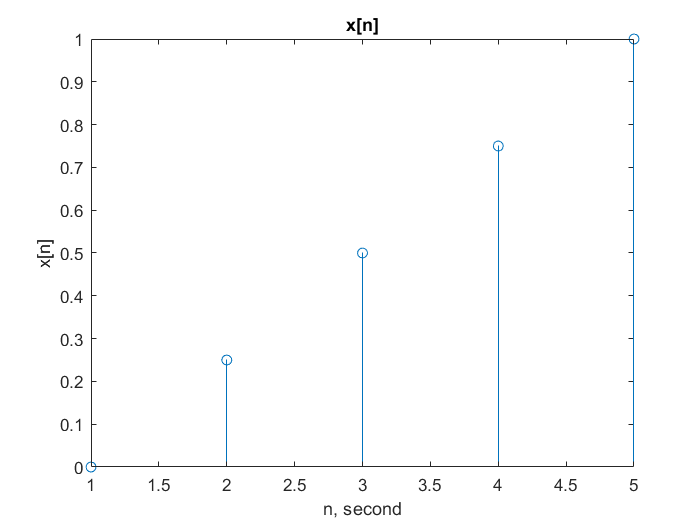

N = [10];   % Assume a value of N
x = [0, 0.25 0.5 0.75 1]; % given sequence
x_p = [zeros(1,length(10*N + 1))];  % CONSTRUCT THIS

% WRITE A CODE SNIPPET TO PLOT x_p[n]

x1 = zeros(1,N);
for i = 1 : N
    if (i > length(x))
        x1(i) = 0;
    else
        x1(i) = x(i); 
    end
end

n1 = -5*N : 1 : 5*N;

for i = 1 : length(n1)
    x_p(i) = x1(rem(rem(n1(i),N)+N , N) + 1);
end

stem(x)
title("x[n]")
xlabel('n, second');
ylabel('x[n]');

stem(n1,x_p)
title("x_p[n]");
xlabel('n, second');
ylabel('x_p[n]');

### **Inference 3 (5 Points):**

- Is $x_p[n]$ is a periodic signal? If yes, what is its fundamental period?  

            ANSWER: Yes, $x_p[n]$ is a periodic signal with **fundamental period N**(in above example

                              fundamental period = 10). 

- What should be the relationship between $L_x$ and $N$to be able to get back $x[n]$ from $x_p[n]$?

            ANSWER: **N  >= **$L_x$, if we want to get back $x[n]$ from $x_p[n]$.

You might have got them right! $x_p[n]$is a periodic sequence with period $N$. Hence, you can express it using Fourier series as follows: 

                                                    $x_p[n] = \sum_{k=0}^{N-1}c_k e^{j2\pi k n/N}$ for $n = 0, \ldots, N-1$, 

where $c_k = \frac{1}{N}\sum_{n=0}^{N-1}x_p[n]e^{-j2\pi kn/N}$ for $k=0,\ldots, N-1$. Note that $c_k=\frac{1}{N}X\left(\frac{2\pi k }{N}\right) $ for $k=0,\ldots, N-1. $

This implies that 

$x_p[n] = \frac{1}{N}\sum_{k=0}^{N-1}X\left(\frac{2\pi k}{N}\right)e^{j2\pi k n/N}$ for $n = 0,\ldots, N-1$. 

The above equation helps in reconstruction of the periodic $x_p[n]$ from the samples of $X(e^{j\omega})$taken at $w = 2\pi k/N$. However, we want to get $x[n]$, not $x_p[n]$!

### **Theory Question 1 (0 Points):**

How and when can we get back $x[n]$ from $X\left(\frac{2\pi k}{N}\right)$values at $k=0,\ldots, N-1$? (Hint: use your Inference 3). 

ANSWER : We can get back $x[n]$ from $X\left(\frac{2\pi k}{N}\right)$ if the value of N is greater than or equal to the length of the sequence $x[n]$.

Note that we can recover, $x[n]$ from $x_p[n]$ when $N \geq L_x$, i.e., when there is no *time-domain aliasing. * In other words, the smallest value of $N$required to get back $x[n]$ is $L_x$. 

The above sampled $X(e^{j 2 \pi k/N})$is called as the $N$-point DFT and denoted simply by $X[k]$. 

Hence, we have the following DFT and IDFT pair for a sequence $x[n]$ with $N \geq L_x$. 

                                                $N$**-point DFT:   **$X[k] = \sum_{n=0}^{N-1}x[n]e^{-j2\pi kn/N}$for $k=0,\ldots, N-1$

                                                $N$**-point IDFT:  **$ x[n] = \frac{1}{N}\sum_{k=0}^{N-1}X[k]e^{j2\pi k n/N}$for $n = 0,\ldots, N-1$. 

Let us now implement the following now. 

### **Coding Question 4 (10 Points):**

- Compute and plot $4$-point DFT and $100-$point DFT of the sequence, $x[n] = [1, 1, 1, 1]$. Plot them in the same figure. You need to think about how you will compute $100
$-point DFT of a sequence of length $4$(Hint: use zero-padding for the last 96 positions to generate a $100
$-point sequence from $x[n]$)

- Compare your answer with the Matlab inbuilt function, [fft](https://in.mathworks.com/help/matlab/ref/fft.html)

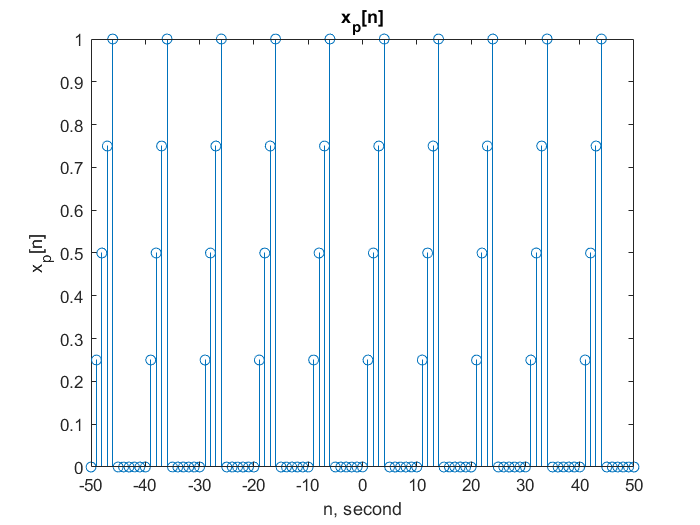

% Write your code here.

%without using inbuilt function

N1 = 100;   % Assume a value of N
N2 = 4;
x = [1 1 1 1]; % given sequence
n = 0 : 1 : 100;
x_padded = (n<4);

X_4 = zeros(1,N2);  %4-point DFT
X_100 = zeros(1,N1); %100-point DFT

for i = 1:length(X_100)    % for 100 point DFT.
    for j = 1 : N1
        X_100(i) = X_100(i) + x_padded(j)*exp(-1i*2*pi*(i-1)*j/N1);
    end
end

for i = 1:length(X_4)  % for 4 point DFT.
    for j = 1:N2
        X_4(i) = X_4(i) + x(j)*exp(-1i*2*pi*(i-1)*j/N2);
    end
end

f_4 = 2*pi*(0 : 1 : length(X_4) - 1)/length(X_4);  % frequency line
f_100 = 2*pi*(0 : 1 : length(X_100) - 1)/length(X_100); % frequency line

subplot(1,1,1)

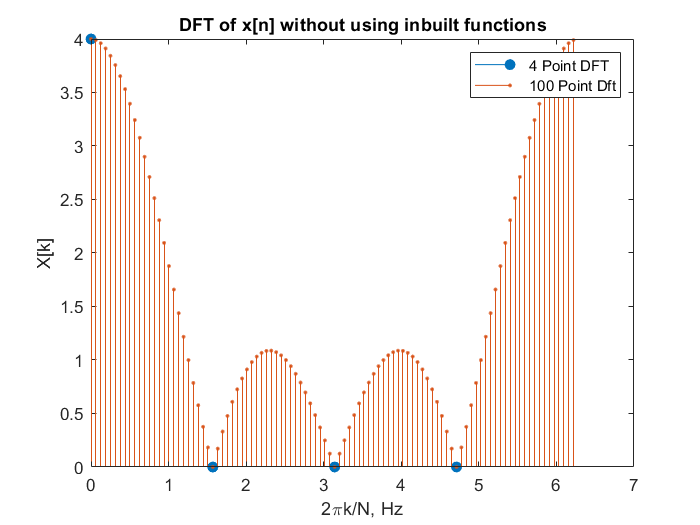

stem(f_4,abs(X_4),'filled');
hold on;
stem(f_100,abs(X_100),'.');
legend("4 Point DFT","100 Point Dft");
title("DFT of x[n] without using inbuilt functions");
xlabel('2\pik/N, Hz');
ylabel('X[k]');
hold off;

%Using inbuilt functions
X_4 = fft(x);
X_100 = fft(x,100);

subplot(1,1,1)

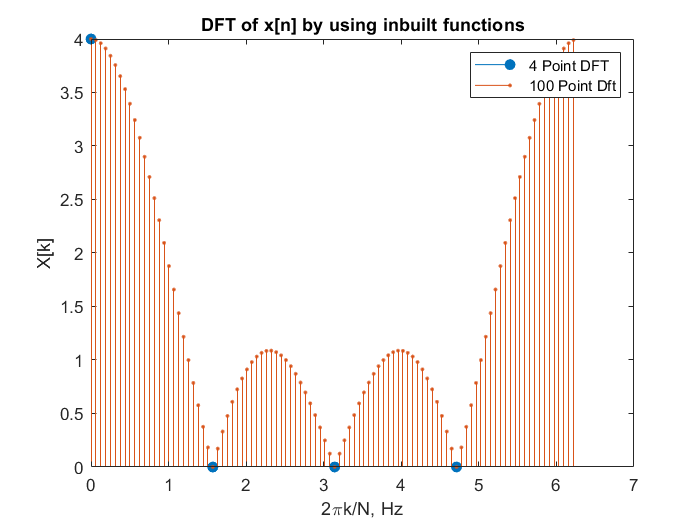

stem(f_4,abs(X_4),"filled");
hold on;
stem(f_100,abs(X_100),'.');
legend("4 Point DFT","100 Point Dft");
title("DFT of x[n] by using inbuilt functions");
xlabel('2\pik/N, Hz');
ylabel('X[k]');
hold off;

- Now, plot the DTFT of $x[n]$ for $\omega\in [-\pi, \pi]$, based on your DFT coefficients. (see [fftshift](https://in.mathworks.com/help/matlab/ref/fftshift.html))

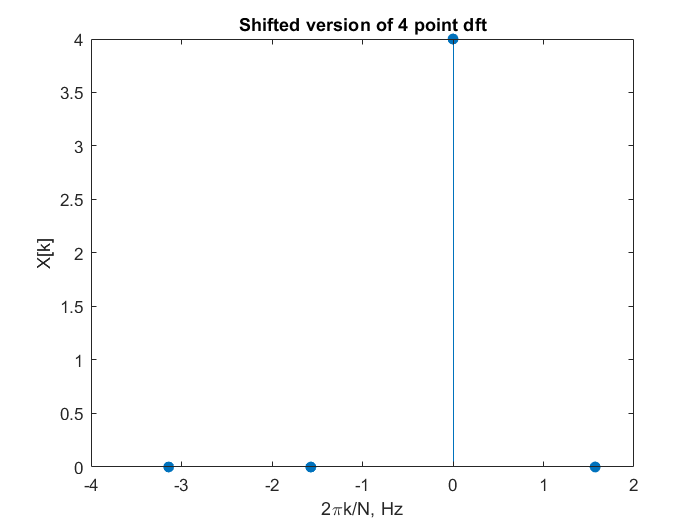

% Write your code here.
n = length(X_4);
fshift_4 = (-n/2:n/2-1)*(2*pi/n);

Xn_4 = fftshift(X_4);
stem(fshift_4,abs(Xn_4),'filled');
title("Shifted version of 4 point dft");
xlabel('2\pik/N, Hz');
ylabel('X[k]');

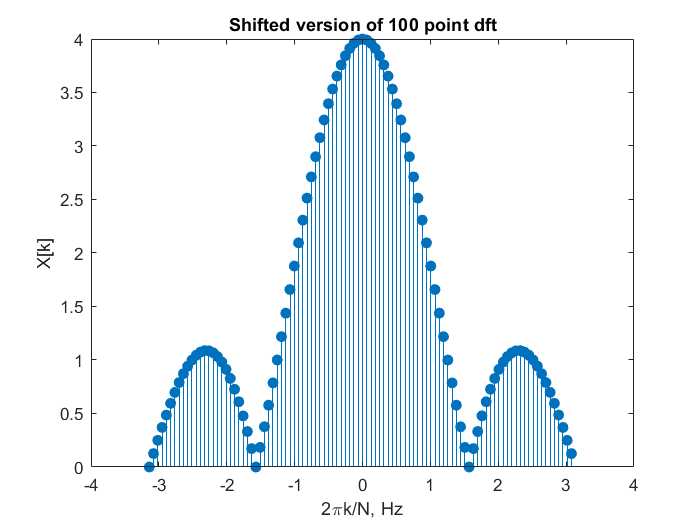


n = length(X_100);
fshift_100 = (-n/2:n/2-1)*(2*pi/n);

Xn_100 = fftshift(X_100);
stem(fshift_100,abs(Xn_100),'filled');
title("Shifted version of 100 point dft");
xlabel('2\pik/N, Hz');
ylabel('X[k]');

### Inference 4 **(10 Points):**

- What are your observations? 

            We can observe that a 4 point DFT is giving just one peak at DC value as [1 1 1 1] han no frequency components, but if we take a look at the 100 point DFT we can see that we are getting a sort of sinc function which gives us an idea that the signal x[n]  which appears as a DC signal, comprises of multiple frequencies

Recall that we wanted to obtain the sequence $y[n]$. We have developed a way to compute a Fourier Transform and its inverse, namely DFT and IDFT of a discrete sequence in a digital computer. Now, can we compute DFTs of $h[n]$ and $x[n]$ to obtain $H[k]$ and $X[k]$, respectively, multiply them and take the IDFT of the result to get $y[n]? $

For answering the above question, recall the following from your Signals and Systems class:

Assume that  $H[k]$ and $X[k]$ are $M$-point DFT of $h[n]$ and $x[n]$, respectively. Then, 

                                                                  $\tilde{y}[n] = M\text{-Point IDFT}(X[k]H[k]) = \sum_{k=0}^{M-1}h[k][x[(n-k)_M]$, for $n = 0,\ldots, M-1$

where $(n-k)_M$ is the modulo $M$value of $(n-k)$which will take a value in $\{0,1, \ldots, M-1\}$. 

The above operation is called the circular *convolution *and it is usually denoted by $\otimes$, i.e., the $M$-point circular convolution of  $h[n]$ and $x[n]$,  $h[n]\otimes x[n] = \sum_{k=0}^{M-1}h[k][x[(n-k)_M]$. 

### Coding Question 5 **(10 Points):**

- Generate $h[n]$ and $x[n]$ of lengths $L_h$ and $L_x$, respectively. 

- Compute $M$-point circular convolution of them. 

- Compute $H[k]$ and $X[k]$,  $M$-point DFTs of $h[n]$ and $x[n]$, respectively for an arbitrary value of $M$. 

- Multiply them to obtain $\tilde{Y}[k]$ and compute its $M$-point IDFT to obtain $\tilde{y}[n]$. 

- Compare your answer with the directly computed convolution above and also by using the  inbuilt Matlab function, [ccnv](https://in.mathworks.com/help/signal/ref/cconv.html). 

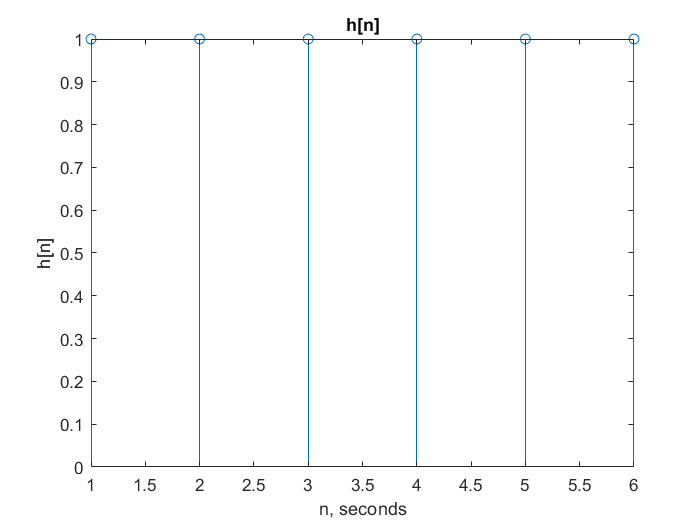

% Write your code here. 
M = 12;

%generating h[n] and x[n]
h = [1 1 1 1 1 1]; %arbitary h[n] 
x = [1 1 1 1 1 1 1 1];%arbitary x[n]

Lh = 6;
Lx = 8;

stem(h); %plot for h[n]
title("h[n]");
xlabel('n, seconds');
ylabel('h[n]');

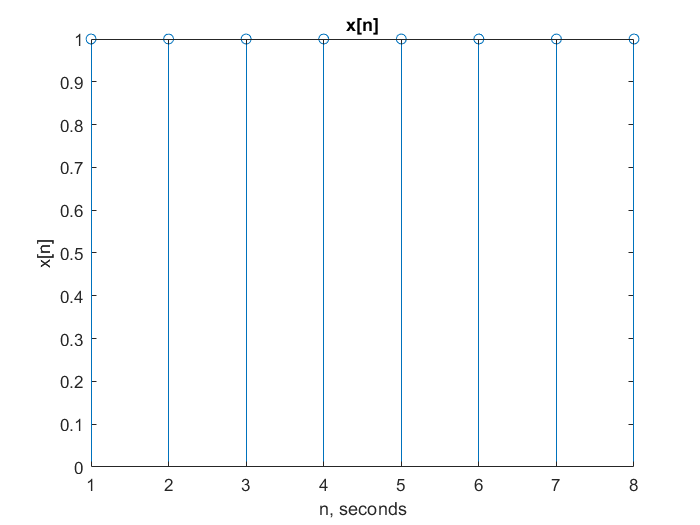


stem(x); %plot for x[n]
title("x[n]");
xlabel('n, seconds');
ylabel('x[n]');

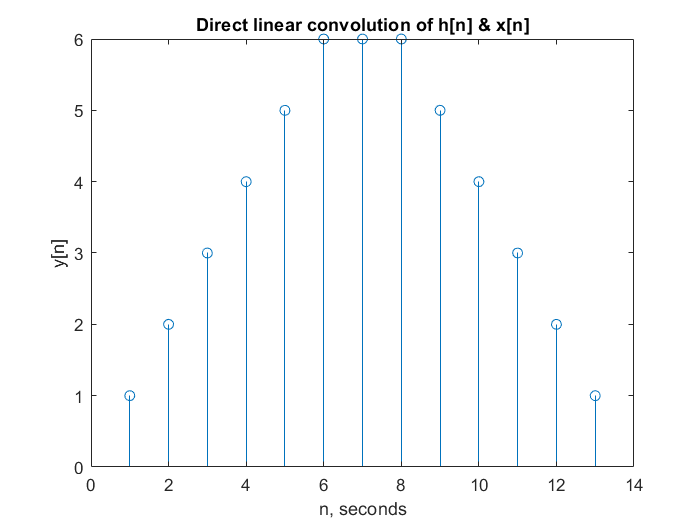


H = fft(h,M); %computing M point DFT of h[n] 
X = fft(x,M); %computing M point DFT of x[n]

Y = H.*X;
y = ifft(Y,M);
c = conv(h,x,'full'); %linear Convolution
c1 = cconv(h,x,M);  %circular Convolution

stem(c);
title("Direct linear convolution of h[n] & x[n]");
xlabel('n, seconds');
ylabel('y[n]');

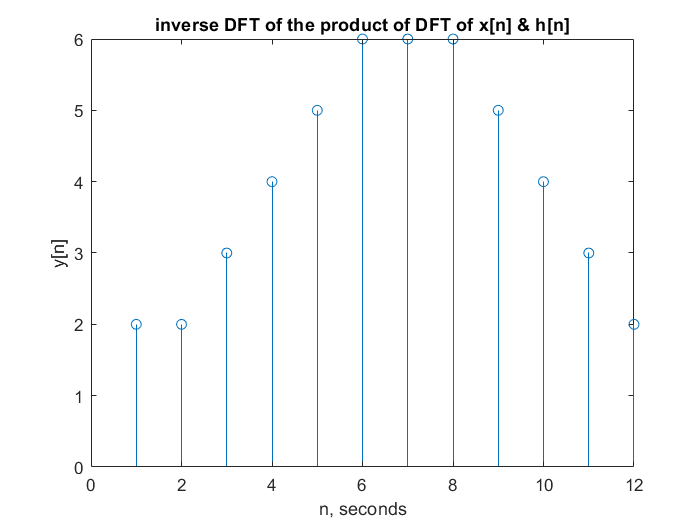


stem(y);
title("inverse DFT of the product of DFT of x[n] & h[n]");
xlabel('n, seconds');
ylabel('y[n]');


stem(c1);
title("circular convolution using inbuilt function");
xlabel('n, seconds');
ylabel('y[n]');

### **Inference (10 Points):**

- For what values of $M$, are $y[n]$ and $\tilde{y}[n]$ will be the same? 

            ANSWER: We know that for circular convolution to be equal to linear convolution M >=  $L_h$ + $L_x$ - 1, in the above example 

                             $L_x$ = 8 and $L_h$ = 6 , hence M >= 13.

                              and we can see that for M = 12 , y[n] and $\tilde{y}[n]$ are different but if we put M = 13 we will get same $y[n]$ and $\tilde{y}[n]$.

Under the above condition on $M$, we can obtain the output $y[n]$using the above technique. Such a technique of obtaining the convolution sum of two finite-length sequences, using the DFT and IDFT operations is called as the *fast convolution. *You may be wondering why it would be fast, as it seems to involve more number of steps than with the *direct convolution * used earlier. However, it turns out that when the DFT and IDFT are computed using any of a large class of algorithms called Fast Fourier Transforms (FFT), fast convolution is more efficient (faster) than the direct convolution.  Hence, the fast convolution is a very important signal processing tool [3]. Can you think of some advantages of direct convolution over the fast convolution? 

# Practical Experiment (50 Points) 

Now, record your voice or some music for $5
$ seconds to obtain $x[n]$ and filter it using the low-pass filter of length M (which you should choose):   

- Speak and record your voice or music for 5 seconds (see [audiorecorder](https://in.mathworks.com/help/matlab/ref/audiorecorder.html) and[ https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering](https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering))

% Write a code snippet to record your voice or some music for 5 seconds and store it in x as an one-dimensional vectors
Fs = 20000;%sampling frequency in Hz
Ts = 1/Fs; %Sampling period

rec =  audiorecorder(Fs , 8 , 1);

disp("Recording......");

Recording......


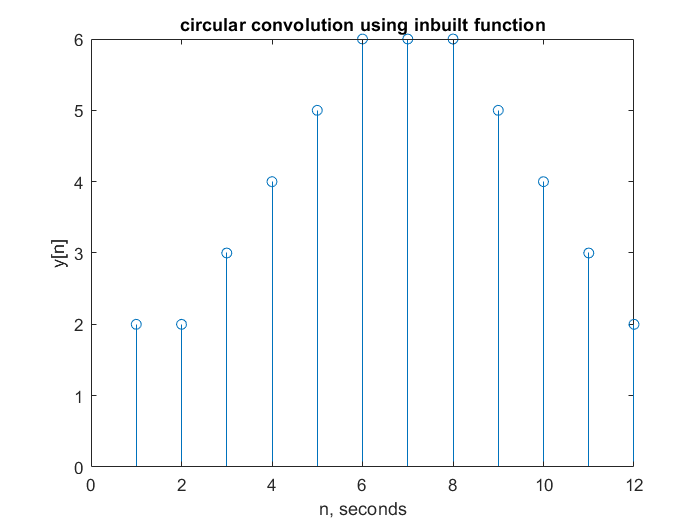

recordblocking(rec,5);

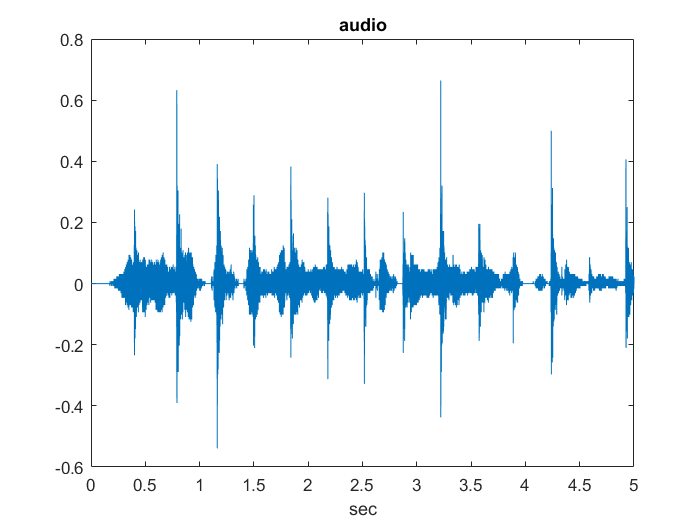


x = getaudiodata(rec);

t = 0 : Ts : 5 - Ts;

plot(t,x);
title("audio");
xlabel('sec');

- Now, using [fft](https://in.mathworks.com/help/matlab/ref/fft.html), roughly find the frequency components in your recorded $x$. 

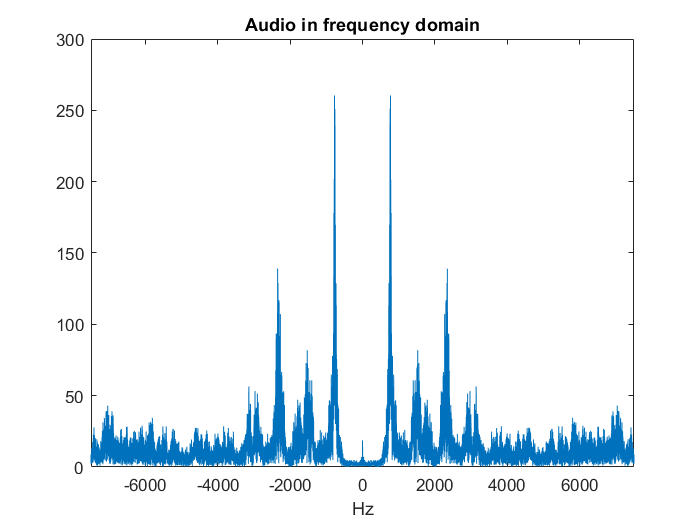

% Write your code here
X = fft(x); %dft of audio data
X = fftshift(X); %circular shifting
f_X = (-numel(X)/2 : 1 : numel(X)/2 - 1)*2*pi/(length(X)*Ts); %frequency axis

plot(f_X,abs(X));
xlim([-7500 7500]);
title("Audio in frequency domain");
xlabel("Hz");

- Now, in order to remove frequencies greater than 3000 Hz components in $x[n]$, design $h[n]$, by finding appropriate $M$.

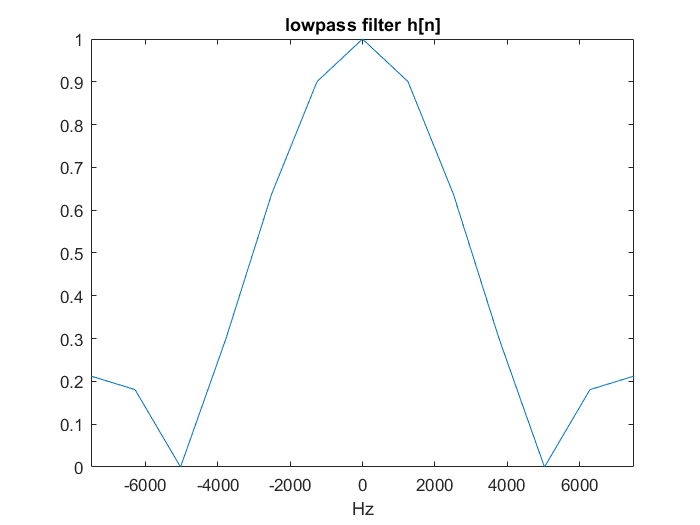

% Sequence h[n] is of length 100 out of which first 25 values are 1/25 and rest are 0
M = [25];  
n1 = 100;
Ts = 1/20000;

h = zeros(1,n); %initiating 100 zeros

%setting first M to 1/M
for i = 1:M
    if (i <= M)
        h(i) = 1/M;
    end
end

H = fft(h);% dft of our filter
H = fftshift(H); %circular shifting

f_H = (-numel(H)/2 : 1 : numel(H)/2 - 1)* 2*pi/(n1*Ts); %frequency axis

plot(f_H,abs(H));
xlim([-7500 7500]);
title("lowpass filter h[n]");
xlabel("Hz");

- Now filter $x[n]$using $h[n]$ and display the output as a plot and sound:

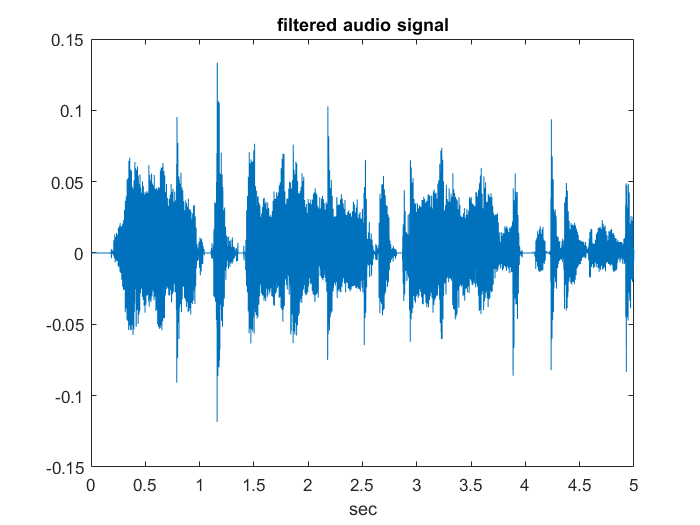

% Filter x using the filter with impulse response h
y =  [conv(x,h,'same')]; %convolving audio with filter

% Plot the output y
plot(t,y); %filtered audio output
title("filtered audio signal");
xlabel('sec');


% Plot y in frequency domain
Y = fft(y);%dft of y
Y = fftshift(Y);%circular shift

f_Y = (-numel(Y)/2 : 1 : numel(Y)/2 - 1)* 2*pi/(length(Y)*Ts); %frequency axis

plot(f_Y,abs(Y));
xlim([-7500 7500]);
title('frequency domian representation of filtered audio.');
xlabel('Hz');

% Output y on your speaker
player = audioplayer(y,20000);
play(player);

- Make observations and write down in the below: 

            ANSWER:   from the above experiment we can see that we can use a moving average function as a lowpass filter in frequency domain provided we have the correct length of sequence ($L_h$) which in the case of moving average function is M, for making a lowpass filter with a cutoff frequency of 3000Hz I have selected M = 25 and overall length of h[n] including the zero elements is 100.

As we can see for the test audio, the frequency components above 3000 Hz got filtered and only the frequencies which were below 3000 Hz are left. 

# (Optional) Convolution and Correlation:

** Note: This part of the code will accounted for your grading**

One more very important operation, similar to the convolution is correlation. Between any two sequences, $x[n]$ and $y[n]$, it is defined as follows:

                                                                           $r_{xy}[l]=\sum_{n=-\infty}^{+\infty}x[n]y[n-l]$.

**Question: **

- How are the convolution  of $x[n]$ and $y[n]$ and correlation of $x[n]$ and $y[n]$ related? 

Let us write some code: 

### Coding Question **(10 Points):**

- Generate a sequence $x[n]$

- Generate another sequence, $y[n] = 0.75x[n-D]$

- Compute the correlation between these two sequences. 

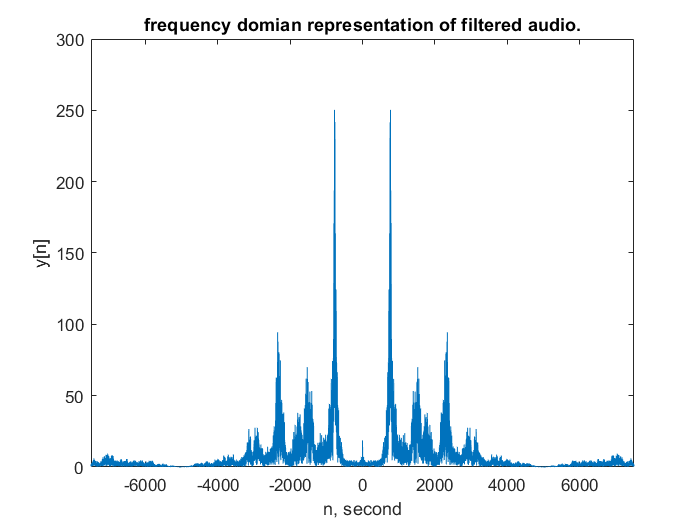


%DID NOT ATTEMPT FULLY AS IT IS OPTIONAL

% Write your code here.
D = 3;
n = 0 : 1 : 14;  % time
w = pi/6;  %Omega
phi = 0;  %phase

x = (n>=5) & (n<10);

y = 0.75*(((n - D)>=5) & ((n - D)<10));

%stem(n,x);
%stem(n,y);

%Correlation

y =  zeros(1,length(n));

j = 1;
while x(j) == 0
    j = j + 1;
end

L1 = j - 1 ;  %L1 is the position of first non zero element of y[n]

for i = L1 :  L1 + (Lx + Lh + 1)  %i iterates from position of first non zero element of y[n] to the last non zero elememt of y[n]    
    for k = 1 : Lh + 1
        %y(i) = y(i) + h(k - n(1))*x(i - k);
    end
end

%stem(n,y);
%title('output sequence y[n] without using inbuilt functions');
xlabel('n, second');
ylabel('y[n]');

### Inference **(10 Points):**

- Is there any relationship between $r_{xy}[l]$ and $D$? Comment. 

            ANSWER:----------------

- What does the correlation of two sequences signify? Think of applications where you can use the correlation operation to find out important parameters (Hint: Note that $D$ is the delay). 

             ANSWER:----------------------

## Other References

- [https://allsignalprocessing.com/](https://allsignalprocessing.com/)

- John G. Proakis and D.G. Manolakis, Digital Signal Processing: Principles, Algorithms and Applications, Prentice Hall, Fourth Edition.

- L.R. Rabiner and B. Gold, Theory and Application of Digital Signal Processing, Prentice Hall, 1992. 

- A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall, 3rd Edition.